依赖[统一实验分析作图v17.1.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/tag/v17.1.0)

行为学重新作图

DataSetBas=TransferLearning.BasicTransferBehaviorDataSet;

SessionTableAL=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="声光水",Design="LightWater");
SessionTableAL.Group(:)="Transfer";
SessionTableLL=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="光声水",Design="LightWater");
SessionTableLL.Group(:)="Original";
SessionTableAA=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="声光水",Design="AudioWater");
SessionTableAA.Group(:)="Original";
SessionTableLA=DataSetBas.TableQuery(["Mouse","DateTime","Performance"],Group="光声水",Design="AudioWater");
SessionTableLA.Group(:)="Transfer";
SummaryL=UniExp.LearningSummarize([SessionTableAL;SessionTableLL]);SummaryA=UniExp.LearningSummarize([SessionTableAA;SessionTableLA]);

要求：黑点白条，窄。去掉坐标轴的边框。左边15 blocks， 右边Y轴10blocks。bar 图的线用2磅

CompareGroup=table(["Original","Transfer"],'VariableNames',"GroupPair");
Colors=[1,1,1;0,0,0];

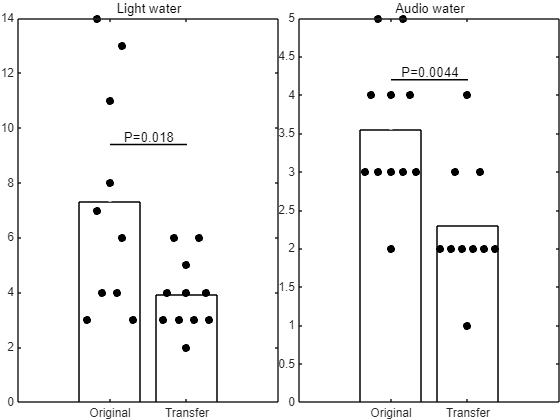

figure;
tiledlayout(1,2,TileSpacing='tight',Padding='tight');
nexttile;
UniExp.BarScatterCompare(struct(Original=SummaryL.LearnedDays{1}.Day,Transfer=SummaryL.LearnedDays{2}.Day),CompareGroup,Colors);
ylim([0,15]);
axis off
title('Light water');
nexttile;
UniExp.BarScatterCompare(struct(Original=SummaryA.LearnedDays{1}.Day,Transfer=SummaryA.LearnedDays{2}.Day),CompareGroup,Colors);
ylim([0,10]);
axis off
title('Audio water');
print(TransferLearning.ProjectPath('BehaviorBar.svg'),'-dsvg')